# Global Planner Simulation with Dijkstra

## Function import

% RUN in file directory
addpath(genpath("../utils/"), genpath("../global_planner/"));

## Initialize

clear all; clc;

% load environment
load("gridmap_15x15_scene8.mat");
map_size = size(grid_map);
G = 1;

% simulation mode
mode = "static";

% start and goal
start = [2, 2];
goal = [14, 14];
% goal = [12, 16];

% planner
% graph search
planner_name = "dijkstra";

## Path planning

planner = str2func(planner_name);
[path, flag, cost, expand] = planner(grid_map, start, goal);

## Visualization

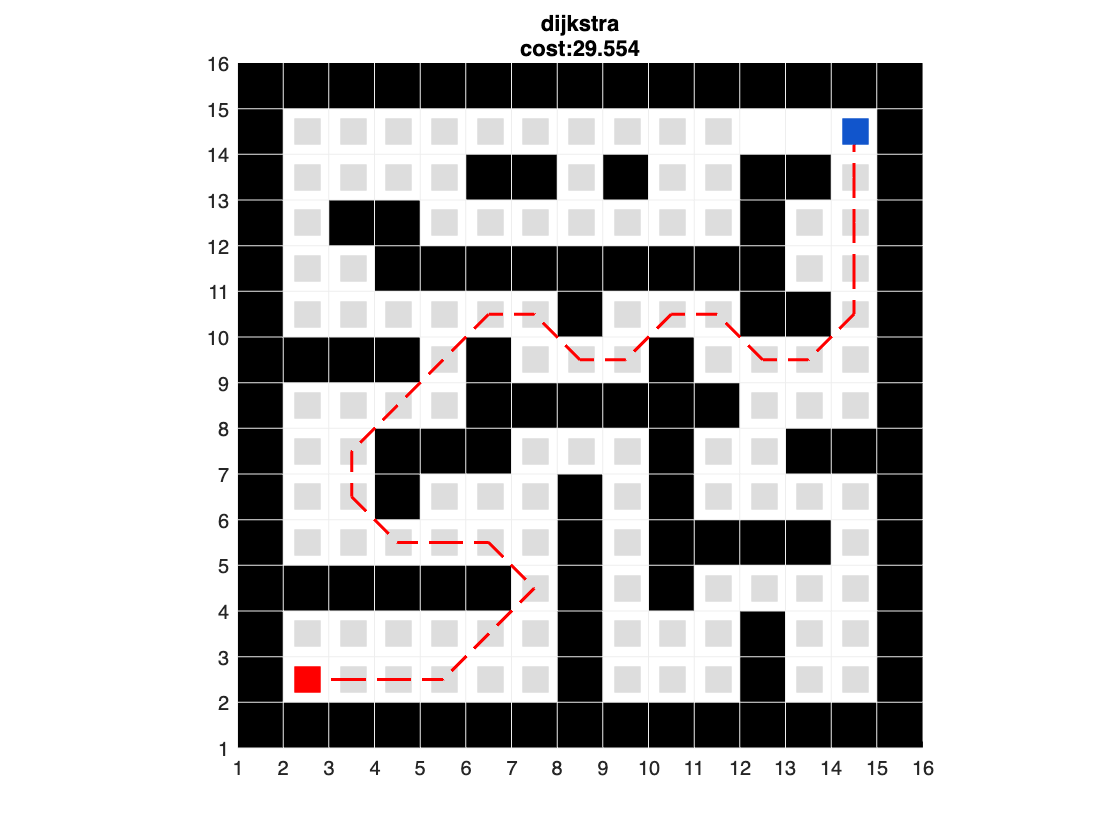

if mode == "static"
    clf; hold on
    
    % plot grid map
    plot_grid(grid_map);
    
    % plot expand zone
    plot_expand(expand, map_size, G, planner_name);
    
    % plot path
    plot_path(path, G);
    
    % plot start and goal
    plot_square(start, map_size, G, "#f00");
    plot_square(goal, map_size, G, "#15c");
    % title
    title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');
    
    hold off
end

## Visualization and modification

Click on the figure to change the state of the grid, the planner will replan.

**Press ENTER in the figure window to exit!**

*Play it!*

if mode == "dynamic"
    while (1)
        clf; hold on
    
        % plot grid map
        plot_grid(grid_map);
    
        % plot expand zone
        plot_expand(expand, map_size, G, planner_name);
    
        % plot path
        plot_path(path, G);
    
        % plot start and goal
        plot_square(start, map_size, G, "#f00");
        plot_square(goal, map_size, G, "#15c");
    
        % title
        title([planner_name, "cost:" + num2str(cost)], 'Interpreter','none');
    
        hold off
    
        % get cursor input
        p = ginput(1);
        if size(p, 1) == 0
            % ENTER means nothing
            break;
        else
            c = floor(p);
    
            % change state on the grid map
            grid_map(c(2), c(1)) = 3 - grid_map(c(2), c(1));
    
            % replan
            [path, flag, cost, expand] = planner(grid_map, start, goal);
        end
    end
end

### Looping through all the grids and storing cost for each grid

costs = {};
means = zeros(1, 10);
standard_deviations = zeros(1, 10);
rng(9876, 'twister');
start_x = randi([2, 14], 10, 1);

for i = 1:10
    filename = 'gridmap_15x15_scene' + i + '.mat';
    load(filename);
    map_size = size(grid_map);
    curr_costs = zeros(1, length(start_x));
    for n = 1:length(start_x)
        [path, flag, cost, expand] = planner(grid_map, [start_x(n), 2], goal);
        curr_costs(n) = cost;
    end
    costs{end+1} = curr_costs;
    means(i) = mean(curr_costs);
    standard_deviations(i) = std(curr_costs);
end

### Display the mean and standard deviations in box plots

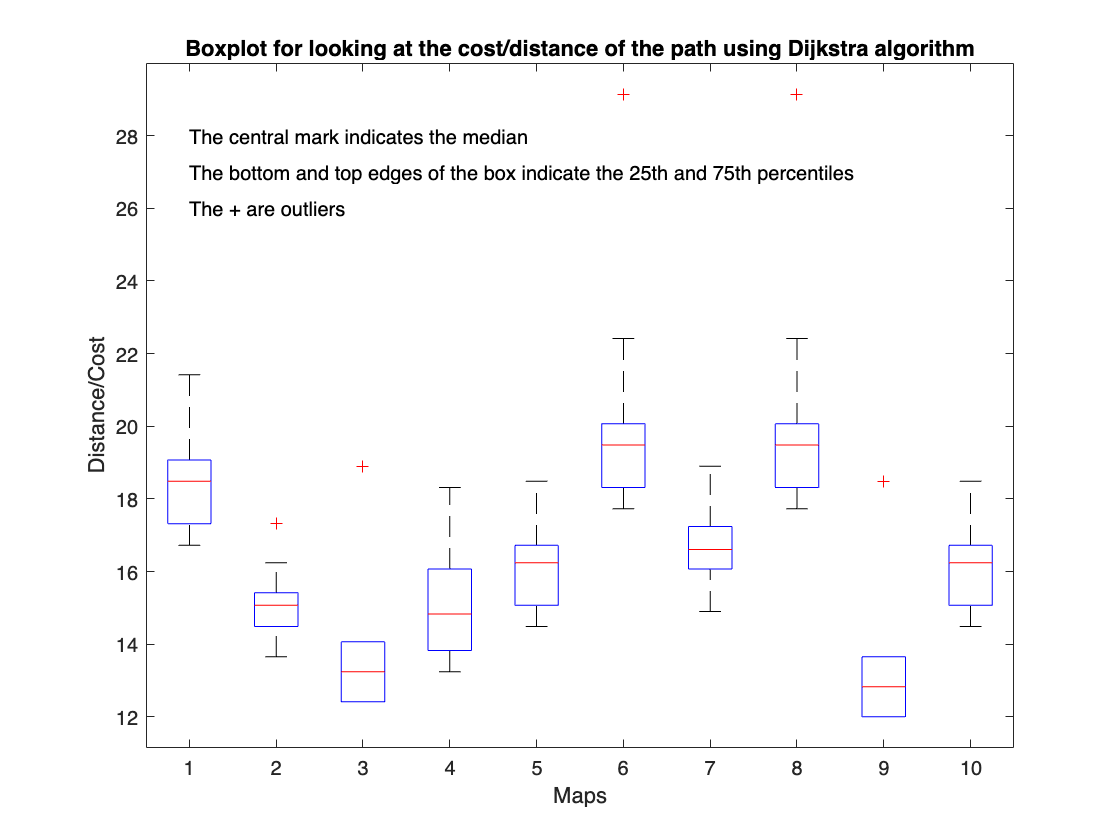

cost_matrix = cell2mat(cellfun(@(x) x(:), costs, 'UniformOutput', false));
boxplot(cost_matrix');
xlabel('Maps');
ylabel('Distance/Cost');
title('Boxplot for looking at the cost/distance of the path using Dijkstra algorithm');
text(1, 28,'The central mark indicates the median');
text(1, 27, 'The bottom and top edges of the box indicate the 25th and 75th percentiles');
text(1, 26, 'The + are outliers');